Es = 1; 
N = 1e5;
p1 = 0.5;


function bit_vec = BitVec(Nbit,pbit)
    bit_vec = rand(1,Nbit) < pbit ;
end

function sym_vec = QAM4SymVec(bit_vec,Es)
    L = length(bit_vec);
    sym_vec = zeros(1,L/2) ;
    for i = 1 : L/2
        a = bit_vec(2*i-1);
        b = bit_vec(2*i);
        s = (-1)^a + (-1)^b * 1i ;
        sym_vec(i) = s / abs(s) * sqrt(Es); 
    end 
end


function [sym_vec_tx,yvec] = QAM4_Rec(SNRb, Es, Nbit, pbit)
    Eb = Es / 2;
    N0 = Eb / SNRb;
    
    B = BitVec(Nbit,pbit);
    sym_vec_tx = QAM4SymVec(B,Es);
    Ns = length(sym_vec_tx);

    CSCN = randn(1,Ns) + randn(1,Ns) * 1i;
    yvec = sym_vec_tx + CSCN * sqrt(N0/2);
end 


function svecdec=QAM4_SymMAPDec(yvec, SNRb, Es, pbit)
    svecdec = zeros(1,length(yvec));
    P = [ (1-pbit)^2 , (1-pbit)*pbit , (pbit)^2 , (1-pbit)*pbit ];
    
    Eb = Es / 2;
    N0 = Eb / SNRb; 
    
    % FIX: Swapped P(2)/P(3) to P(3)/P(2) to align 'Left/Right' ratio 
    % with 'Bottom/Top' logic used in bias_Im
    bias_Re = N0/2 * log(P(3)/P(2)); 
    bias_Im = N0/2 * log(P(2)/P(1));

    for i = 1 : length(yvec)
        y = yvec(i);
        a = real(y);
        b = imag(y);
        
        s_raw = (-1)^((a >= bias_Re)+1) + (-1)^((b >= bias_Im)+1) * 1i;
        
        svecdec(i) = s_raw / abs(s_raw) * sqrt(Es);
    end
end


function ser=CompSER(sym_vec_tx,svecdec)
    ser = 1 - sum(abs(sym_vec_tx - svecdec) < 1e-5) / length(sym_vec_tx);
end


SNR_s = -6 : 6;
SER = zeros(1,length(SNR_s));

for i = 1 : length(SNR_s)
    SNRb_DB = SNR_s(i);
    SNRb = 10^(SNRb_DB/10);
    [S,Y] = QAM4_Rec(SNRb, Es, N, p1);
    S_dec = QAM4_SymMAPDec(Y, SNRb, Es, p1);
    
    ser = CompSER(S,S_dec);
    SER(i) = ser;
end 


disp('SNR (dB):');

SNR (dB):


disp(SNR_s);

    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6



disp('SER:');

SER:


disp(SER);

    0.4196    0.3858    0.3413    0.2886    0.2444    0.1980    0.1492    0.1068    0.0725    0.0453    0.0246    0.0116    0.0044



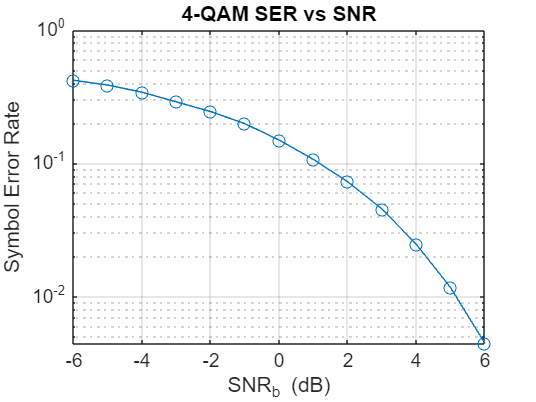

figure
semilogy(SNR_s, SER, '-o');
grid on;
title('4-QAM SER vs SNR');
xlabel('SNR_b (dB)');
ylabel('Symbol Error Rate');

p1_s = 0.01: 0.01 : 0.99;
SER = zeros(1,length(p1_s));
SNRb_DB = -3;

for i = 1 : length(p1_s)
    p1 = p1_s(i);
    SNRb = 10^(SNRb_DB/10);
    [S,Y] = QAM4_Rec(SNRb, Es, N, p1);
    S_dec = QAM4_SymMAPDec(Y, SNRb, Es, p1);
    
    ser = CompSER(S,S_dec);
    SER(i) = ser;
end 


disp('p1:');

p1:


disp(p1_s);

    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900    0.5000    0.5100    0.5200    0.5300    0.5400    0.5500    0.5600    0.5700    0.5800    0.5900    0.6000    0.6100    0.6200    0.6300    0.6400    0.6500    0.6600    0.6700    0.6800    0.6900    0.7000    0.7100    0.7200    0.7300    0.7400    0.7500    0.7600    0.7700    0.7800    0.7900    0.8000    0.8100    0.8200    0.8300    0.8400    0.8500    0.8600    0.8700    0.8800    0.8900    0.9000    0.9100    0.9200    0.9300    0.9400    0.9500    0.9600    0.9700    0.9800    0.9900



disp('SER:');

SER:


disp(SER);

    0.0195    0.0376    0.0564    0.0714    0.0853    0.1005    0.1147    0.1232    0.1377    0.1464    0.1554    0.1639    0.1720    0.1805    0.1884    0.1960    0.2052    0.2076    0.2160    0.2195    0.2280    0.2322    0.2383    0.2423    0.2419    0.2458    0.2545    0.2586    0.2620    0.2642    0.2638    0.2694    0.2741    0.2720    0.2754    0.2809    0.2795    0.2827    0.2836    0.2877    0.2838    0.2850    0.2851    0.2881    0.2909    0.2904    0.2940    0.2931    0.2905    0.2911    0.2894    0.2899    0.2906    0.2899    0.2919    0.2876    0.2908    0.2885    0.2849    0.2834    0.2832    0.2818    0.2780    0.2774    0.2761    0.2738    0.2736    0.2668    0.2643    0.2625    0.2595    0.2535    0.2510    0.2479    0.2473    0.2414    0.2353    0.2337    0.2259    0.2263    0.2114    0.2079    0.2033    0.1944    0.1913    0.1804    0.1711    0.1672    0.1554    0.1452    0.1327    0.1237    0.1112    0.0983    0.0876    0.0705    0.0537    0.0383    0.0197



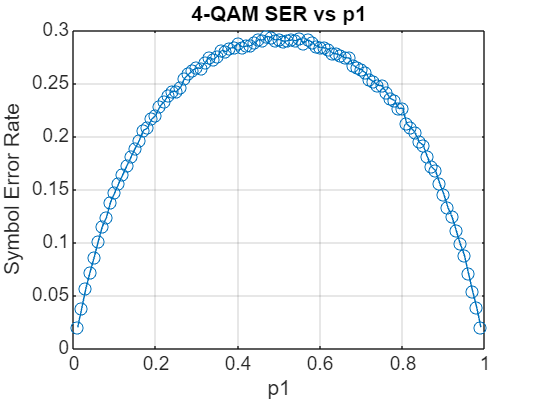

figure
plot(p1_s, SER, '-o');
grid on;
title('4-QAM SER vs p1');
xlabel('p1');
ylabel('Symbol Error Rate');

Es = 1; 
Nsym = 1e5;

function sym_vec = QAM8SymVec(Nsym, Es)
    sqEs = sqrt(Es);
    
    S0 =  sqEs + 1i*(sqEs/2);
    S1 =  sqEs - 1i*(sqEs/2);
    S2 =  (sqEs/2) + 1i*0;
    S3 =  0 + 1i*(sqEs/2);
    S4 =  0 - 1i*(sqEs/2);
    S5 = -(sqEs/2) + 1i*0;
    S6 = -sqEs + 1i*(sqEs/2);
    S7 = -sqEs - 1i*(sqEs/2);
    
    Constellation = [S0, S1, S2, S3, S4, S5, S6, S7];
    
    indices = randi([1, 8], 1, Nsym);
    sym_vec = Constellation(indices);
end

function yvec = QAM8_Rec(sym_vec8, SNRb, Es)
    E_avg = 0.75 * Es;
    Eb = E_avg / 3;
    N0 = Eb / SNRb;
    
    Ns = length(sym_vec8);
    noise = (randn(1, Ns) + 1i*randn(1, Ns)) * sqrt(N0/2);
    yvec = sym_vec8 + noise;
end 

function svecdec = QAM8_SymMAPDec(yvec, Es)
    sqEs = sqrt(Es);
    Constellation = [ ...
         (sqEs + 1i*sqEs/2), ...
         (sqEs - 1i*sqEs/2), ...
         (sqEs/2 + 1i*0), ...
         (0 + 1i*sqEs/2), ...
         (0 - 1i*sqEs/2), ...
         (-sqEs/2 + 1i*0), ...
         (-sqEs + 1i*sqEs/2), ...
         (-sqEs - 1i*sqEs/2) ];
         
    svecdec = zeros(1, length(yvec));
    
    for i = 1 : length(yvec)
        y = yvec(i);
        [~, idx] = min(abs(y - Constellation).^2);
        svecdec(i) = Constellation(idx);
    end
end

SNR_dB = -25 : 1 : 0;
SER_Sim = zeros(1, length(SNR_dB));
SER_Theory = zeros(1, length(SNR_dB));

for i = 1 : length(SNR_dB)
    snr_db_val = SNR_dB(i);
    SNRb = 10^(snr_db_val/10);
    
    S = QAM8SymVec(Nsym, Es);
    Y = QAM8_Rec(S, SNRb, Es);
    S_dec = QAM8_SymMAPDec(Y, Es);
    
    SER_Sim(i) = CompSER(S, S_dec);
    SER_Theory(i) = 3 * 0.5 * erfc(sqrt(SNRb)/sqrt(2));
end 


disp('SNR (dB):'); disp(SNR_dB);

SNR (dB):
   -25   -24   -23   -22   -21   -20   -19   -18   -17   -16   -15   -14   -13   -12   -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0



disp('SER Sim:'); disp(SER_Sim);

SER Sim:
    0.8504    0.8470    0.8435    0.8388    0.8349    0.8294    0.8243    0.8153    0.8117    0.8006    0.7900    0.7778    0.7680    0.7528    0.7336    0.7131    0.6918    0.6638    0.6377    0.6070    0.5685    0.5277    0.4825    0.4337    0.3782    0.3266



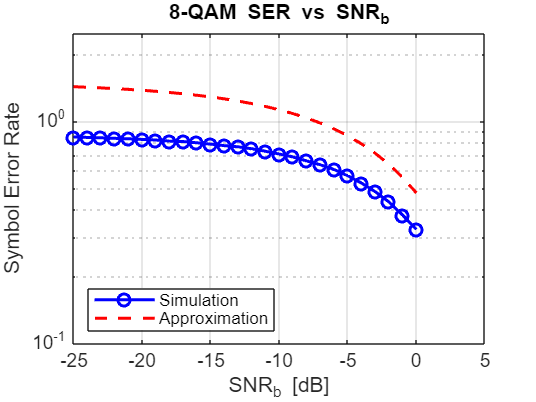


figure;
semilogy(SNR_dB, SER_Sim, 'bo-', 'LineWidth', 1.5);
hold on;
semilogy(SNR_dB, SER_Theory, 'r--', 'LineWidth', 1.5);
grid on;
title('8-QAM SER vs SNR_b');
xlabel('SNR_b [dB]');
ylabel('Symbol Error Rate');
legend('Simulation', 'Approximation', 'Location', 'southwest');
axis([-25 5 1e-1 2.5]);

% --- 1. OFDM Modulator (Item 2.2.1) ---
function xofdm = OFDM_Mod(bit_stream, Nsc, Ncp, constellation)
    % constellation: 'BPSK', '4QAM', '8QAM'
    
    % 1. Determine Bits per Symbol (M) and Constellation Mapping
    if strcmp(constellation, 'BPSK')
        M_bits = 1;
        Es = 1; 
        % BPSK: 0->-1, 1->1 (Standard)
        map_func = @(b) (2*b - 1) * sqrt(Es); 
        
    elseif strcmp(constellation, '4QAM')
        M_bits = 2;
        Es = 1;
        % 4QAM Fig 1: 00->S0, 01->S1, 11->S2, 10->S3
        % Derived in Part 1
        % 00 -> 1+j, 01 -> 1-j, 11 -> -1-j, 10 -> -1+j (Scaled)
        map_func = @QAM4_Mapper;
        
    elseif strcmp(constellation, '8QAM')
        M_bits = 3;
        Es = 1;
        % 8QAM Fig 2 Mapping (Gray-like implementation)
        map_func = @QAM8_Mapper;
    else
        error('Unknown constellation');
    end
    
    % 2. Pad bits to ensure integer number of OFDM symbols
    % Bits per OFDM symbol = Nsc * M_bits
    bits_per_ofdm = Nsc * M_bits;
    L = length(bit_stream);
    remainder = mod(L, bits_per_ofdm);
    if remainder ~= 0
        padding = randi([0 1], 1, bits_per_ofdm - remainder);
        bit_stream = [bit_stream, padding];
    end
    
    num_bits = length(bit_stream);
    num_syms = num_bits / M_bits;     % Number of constellation symbols
    num_ofdm = num_syms / Nsc;        % Number of OFDM symbols (m)
    
    % 3. Map Bits to Symbols
    const_symbols = zeros(1, num_syms);
    for i = 1:num_syms
        b_idx = (i-1)*M_bits + 1;
        bits = bit_stream(b_idx : b_idx+M_bits-1);
        const_symbols(i) = map_func(bits);
    end
    
    % 4. Reshape to Matrix m x Nsc
    % Each row is an OFDM symbol (Frequency domain data D_m,k)
    % Note: MATLAB fills columns first, so we transpose
    sym_matrix = reshape(const_symbols, Nsc, num_ofdm).'; 
    
    % 5. IDFT
    % Instructions: Use ifft and multiply by sqrt(Nsc)
    % ifft operates on columns, so we apply to transpose of sym_matrix or adjust
    % The matrix is m (rows) x Nsc (cols). We want IDFT of each row.
    % ifft(X, [], 2) operates on rows.
    
    % time_matrix = ifft(sym_matrix, [], 2) * sqrt(Nsc); 
    % However, instruction 2.2.1 says "ifft operates on each column...".
    % So let's align with instructions: Transpose to Nsc x m
    sym_matrix_T = sym_matrix.'; % Size Nsc x m
    time_matrix_T = ifft(sym_matrix_T) * sqrt(Nsc); % Nsc x m
    
    % 6. Add Cyclic Prefix (CP)
    % Append last Ncp samples to the front
    cp_part = time_matrix_T(end-Ncp+1:end, :);
    ofdm_syms_T = [cp_part; time_matrix_T]; % Size (Nsc+Ncp) x m
    
    % 7. Serialize
    xofdm = ofdm_syms_T(:).'; % Output vector
end

% --- Helper Mappers ---
function s = QAM4_Mapper(bits)
    % 00->S0, 01->S1, 11->S2, 10->S3 (From Part 1)
    % S0=1+j, S1=1-j, S2=-1-j, S3=-1+j (Unscaled)
    % Es=1 -> Scale by 1/sqrt(2)
    b = bits(1)*2 + bits(2);
    scale = 1/sqrt(2);
    switch b
        case 0 % 00
            s = (1 + 1i) * scale;
        case 1 % 01
            s = (1 - 1i) * scale;
        case 3 % 11
            s = (-1 - 1i) * scale;
        case 2 % 10
            s = (-1 + 1i) * scale;
    end
end

function s = QAM8_Mapper(bits)
    % 8QAM Fig 2 Constellation with Es=1
    % Mapping 3 bits -> Point
    % Defined Gray Mapping for consistency
    % 000->S3, 001->S0, 011->S1, 010->S4
    % 110->S7, 111->S6, 101->S5, 100->S2
    
    % S0 = sqEs + j*sqEs/2
    % S1 = sqEs - j*sqEs/2
    % S2 = sqEs/2
    % S3 = j*sqEs/2
    % S4 = -j*sqEs/2
    % S5 = -sqEs/2
    % S6 = -sqEs + j*sqEs/2
    % S7 = -sqEs - j*sqEs/2
    
    Es = 1;
    sqEs = sqrt(Es);
    
    dec = bits(1)*4 + bits(2)*2 + bits(3);
    
    switch dec
        case 0 % 000 -> S3
            s = 0 + 1i*(sqEs/2);
        case 1 % 001 -> S0
            s = sqEs + 1i*(sqEs/2);
        case 3 % 011 -> S1
            s = sqEs - 1i*(sqEs/2);
        case 2 % 010 -> S4
            s = 0 - 1i*(sqEs/2);
        case 6 % 110 -> S7
            s = -sqEs - 1i*(sqEs/2);
        case 7 % 111 -> S6
            s = -sqEs + 1i*(sqEs/2);
        case 5 % 101 -> S5
            s = -(sqEs/2) + 1i*0;
        case 4 % 100 -> S2
            s = (sqEs/2) + 1i*0;
    end
end


% --- 2. Wireless Channel (Item 2.2.2) ---
function [r1ofdm, r2ofdm] = Wireless_Channel(xofdm, N0)
    % Constants
    omega0 = 2 * pi * sqrt(2);
    
    % Channel 1 Def
    a1_vals = [8.1, 2.3, 5, 2.3, 1.9, 0.5];
    a1 = (1/10.2424) * a1_vals;
    L1 = length(a1);
    h1 = zeros(1, L1);
    for n = 0:L1-1
        h1(n+1) = a1(n+1) * exp(1i * omega0 * n);
    end
    
    % Channel 2 Def
    a2_vals = [8.1, 2.3, 5, 2.3, 1.9, 0.5, 3, 1.1, 0.9, 0.35, 1.5, 2, 3];
    a2 = (1/11.4648) * a2_vals;
    L2 = length(a2);
    h2 = zeros(1, L2);
    for n = 0:L2-1
        h2(n+1) = a2(n+1) * exp(1i * omega0 * n);
    end
    
    % Apply Convolutions
    r1_conv = conv(xofdm, h1);
    r2_conv = conv(xofdm, h2);
    
    % Truncate to length of input
    Lx = length(xofdm);
    r1_trunc = r1_conv(1:Lx);
    r2_trunc = r2_conv(1:Lx);
    
    % Generate Noise
    % CN(0, N0) -> Real/Imag parts have var N0/2
    noise = (randn(1, Lx) + 1i*randn(1, Lx)) * sqrt(N0/2);
    
    % Add Noise
    r1ofdm = r1_trunc + noise;
    r2ofdm = r2_trunc + noise;
end


% --- 3. OFDM Demodulator (Item 2.2.3) ---
function dec_bits = OFDM_Demod(rvec, Nsc, Ncp, constellation, Channel)
    
    % 1. Reconstruct Channel Freq Response H[k]
    omega0 = 2 * pi * sqrt(2);
    if Channel == 1
        a_vals = [8.1, 2.3, 5, 2.3, 1.9, 0.5];
        norm_fac = 1/10.2424;
    else
        a_vals = [8.1, 2.3, 5, 2.3, 1.9, 0.5, 3, 1.1, 0.9, 0.35, 1.5, 2, 3];
        norm_fac = 1/11.4648;
    end
    a = norm_fac * a_vals;
    L = length(a);
    h = zeros(1, L);
    for n = 0:L-1
        h(n+1) = a(n+1) * exp(1i * omega0 * n);
    end
    % H[k] is DFT of h, length Nsc (Zero padded)
    H_k = fft(h, Nsc);
    
    % 2. Reshape Received Signal
    Nsym = Nsc + Ncp;
    num_samples = length(rvec);
    m = floor(num_samples / Nsym);
    
    % Reshape to (Nsc+Ncp) x m (Columns are OFDM symbols)
    r_matrix = reshape(rvec(1:m*Nsym), Nsym, m);
    
    % 3. Remove CP
    % Take samples Ncp+1 to End
    r_no_cp = r_matrix(Ncp+1:end, :); % Size Nsc x m
    
    % 4. DFT
    % fft(X) works on columns. Divide by sqrt(Nsc)
    y_freq = fft(r_no_cp) / sqrt(Nsc); % Size Nsc x m
    
    % 5. Zero-Forcing Equalization
    % Divide by H[k]. H_k is vector Nsc x 1.
    % We need to divide every column of y_freq by H_k
    H_k_mat = repmat(H_k.', 1, m); % Ensure H_k is column
    
    sym_est_mat = y_freq ./ H_k_mat;
    
    % Serialize to vector of symbols
    sym_est_vec = sym_est_mat.'; % Transpose to get row-by-row
    sym_est_vec = sym_est_vec(:).';
    
    % 6. Demap / Decode Bits
    dec_bits = [];
    
    % Need inverse of the mappers defined in Modulator
    if strcmp(constellation, 'BPSK')
        % BPSK Demap: Real > 0 -> 1, Real < 0 -> 0
        % Map used: (2b-1) -> 0 maps to -1, 1 maps to 1
        % If Real > 0 -> Bit 1
        % If Real < 0 -> Bit 0
        dec_bits = real(sym_est_vec) > 0;
        
    elseif strcmp(constellation, '4QAM')
        % 4QAM Demap (ML/MAP)
        % Using S0..S3 map
        % Simple slicer:
        % Re > 0, Im > 0 -> 00
        % Re > 0, Im < 0 -> 01
        % Re < 0, Im > 0 -> 10
        % Re < 0, Im < 0 -> 11
        L = length(sym_est_vec);
        dec_bits = zeros(1, 2*L);
        for i = 1:L
            re = real(sym_est_vec(i));
            im = imag(sym_est_vec(i));
            if re >= 0 && im >= 0
                b = [0 0];
            elseif re >= 0 && im < 0
                b = [0 1];
            elseif re < 0 && im >= 0
                b = [1 0];
            else
                b = [1 1];
            end
            dec_bits(2*i-1 : 2*i) = b;
        end
        
    elseif strcmp(constellation, '8QAM')
        % 8QAM Demap (ML)
        % Constellation points (Same as Modulator)
        Es = 1; sqEs = sqrt(Es);
        S = [ (0+1i*sqEs/2), (sqEs+1i*sqEs/2), (sqEs-1i*sqEs/2), (0-1i*sqEs/2), ...
              (-sqEs-1i*sqEs/2), (-sqEs+1i*sqEs/2), (-sqEs/2), (sqEs/2) ];
        % Bit patterns corresponding to indices 1..8
        % 1:000, 2:001, 3:011, 4:010, 5:110, 6:111, 7:101, 8:100
        BitsMap = [0 0 0; 0 0 1; 0 1 1; 0 1 0; 1 1 0; 1 1 1; 1 0 1; 1 0 0];
        
        L = length(sym_est_vec);
        dec_bits = zeros(1, 3*L);
        
        for i = 1:L
            val = sym_est_vec(i);
            [~, idx] = min(abs(val - S).^2); % Min Distance
            dec_bits(3*i-2 : 3*i) = BitsMap(idx, :);
        end
    end
end



